#### Tyler Jones

#### 08.17.2023

# **Savings Calculator**

#### The purpose of this live script is to use the gathered and analyzed data in order to produce a working calculator to project savings

#### Note: Savings goal for switching to dual pad printing is **$0.145** per part

### 2022 Metrics

% Initialize constants
GOOD_QTY = 11868; % amount of good parts
BAD_QTY = 1405; % amount of bad parts
DESIRED_QTY = 10692; % the requested amount of good parts
RECIEVED_QTY = 10939; % the actual amount of good parts delivered
ACTUAL_RUN_TIME = 180.33; % hr
HOURLY_RATE = 20;
GOAL_PCS_PER_HOUR = 64; % goal pieces per hr

% Calculations
total_qty = GOOD_QTY + BAD_QTY; % total parts passed through Pad printing
estimated_run_time = total_qty/GOAL_PCS_PER_HOUR; % pcs/hr
adjusted_estimated_run_time = RECIEVED_QTY/GOAL_PCS_PER_HOUR; % pcs/hr
total_pcs_per_hour = total_qty/ACTUAL_RUN_TIME; % pcs/hr
good_pcs_per_hour = GOOD_QTY/ACTUAL_RUN_TIME; % good pcs/hr
bad_pcs_per_hour = BAD_QTY/ACTUAL_RUN_TIME; % bad pcs/hr
goal_difference = good_pcs_per_hour - GOAL_PCS_PER_HOUR; % pcs/hr
efficiency = adjusted_estimated_run_time/ACTUAL_RUN_TIME*100; % efficiency of operation
estimated_labor = HOURLY_RATE*estimated_run_time; % $
actual_labor = HOURLY_RATE*ACTUAL_RUN_TIME; % $
labor_variance = estimated_labor - actual_labor; % $

% Print the savings
savings_2022 = labor_variance/total_qty; % $/(total parts)
fprintf('2022 Savings: $%.4f [$/part]',savings_2022)

2022 Savings: $0.0408 [$/part]

good_savings_2022 = labor_variance/GOOD_QTY; % $/(good parts)
fprintf('2022 Good Savings: $%.4f [$/part]',good_savings_2022)

2022 Good Savings: $0.0456 [$/part]

### Old 2023 Metrics

% Initialize constants
GOOD_QTY = 5897; % amount of good parts
BAD_QTY = 1038; % amount of bad parts
DESIRED_QTY = 5148; % the requested amount of good parts
RECIEVED_QTY = 7142; % the actual amount of good parts delivered
ACTUAL_RUN_TIME = 141.19; % hr
HOURLY_RATE = 20;
GOAL_PCS_PER_HOUR = 64; % goal pieces per hr

% Calculations
total_qty = GOOD_QTY + BAD_QTY; % total parts passed through Pad printing
estimated_run_time = total_qty/GOAL_PCS_PER_HOUR; % pcs/hr
adjusted_estimated_run_time = RECIEVED_QTY/GOAL_PCS_PER_HOUR; % pcs/hr
total_pcs_per_hour = total_qty/ACTUAL_RUN_TIME; % pcs/hr
good_pcs_per_hour = GOOD_QTY/ACTUAL_RUN_TIME; % good pcs/hr
bad_pcs_per_hour = BAD_QTY/ACTUAL_RUN_TIME; % bad pcs/hr
goal_difference = good_pcs_per_hour - GOAL_PCS_PER_HOUR; % pcs/hr
efficiency = adjusted_estimated_run_time/ACTUAL_RUN_TIME*100; % efficiency of operation
estimated_labor = HOURLY_RATE*estimated_run_time; % $
actual_labor = HOURLY_RATE*ACTUAL_RUN_TIME; % $
labor_variance = estimated_labor - actual_labor; % $

% Print the savings
savings_old_2023 = labor_variance/total_qty; % $/(total parts)
fprintf('2023-Old Savings: $%.4f [$/part]',savings_old_2023)

2023-Old Savings: $-0.0947 [$/part]

good_savings_old_2023 = labor_variance/GOOD_QTY; % $/(good parts)
fprintf('2023-Old Good Savings: $%.4f [$/part]',good_savings_old_2023)

2023-Old Good Savings: $-0.1113 [$/part]

### New 2023 Metrics

% Initialize constants
GOOD_QTY = 3831 + 150; % amount of good parts
BAD_QTY = 59 + 1; % amount of bad parts
DESIRED_QTY = 3831 + 150; % the requested amount of good parts
RECIEVED_QTY = 3831 + 150; % the actual amount of good parts delivered
ACTUAL_RUN_TIME = 49.19 + 1.5; % hr
HOURLY_RATE = 20;
GOAL_PCS_PER_HOUR = 64; % goal pieces per hr

% Calculations
total_qty = GOOD_QTY + BAD_QTY; % total parts passed through Pad printing
estimated_run_time = total_qty/GOAL_PCS_PER_HOUR; % pcs/hr
adjusted_estimated_run_time = RECIEVED_QTY/GOAL_PCS_PER_HOUR; % pcs/hr
total_pcs_per_hour = total_qty/ACTUAL_RUN_TIME; % pcs/hr
good_pcs_per_hour = GOOD_QTY/ACTUAL_RUN_TIME; % good pcs/hr
bad_pcs_per_hour = BAD_QTY/ACTUAL_RUN_TIME; % bad pcs/hr
goal_difference = good_pcs_per_hour - GOAL_PCS_PER_HOUR; % pcs/hr
efficiency = adjusted_estimated_run_time/ACTUAL_RUN_TIME*100; % efficiency of operation
estimated_labor = HOURLY_RATE*estimated_run_time; % $
actual_labor = HOURLY_RATE*ACTUAL_RUN_TIME; % $
labor_variance = estimated_labor - actual_labor; % $

% Print the savings
savings_new_2023 = labor_variance/total_qty; % $/(total parts)
fprintf('2023-New Savings: $%.4f ',savings_new_2023)

2023-New Savings: $0.0616 

good_savings_new_2023 = labor_variance/GOOD_QTY; % $/(good parts)
fprintf('2023-New Good Savings: $%.4f [$/part]',good_savings_new_2023)

2023-New Good Savings: $0.0626 [$/part]

### Analysis

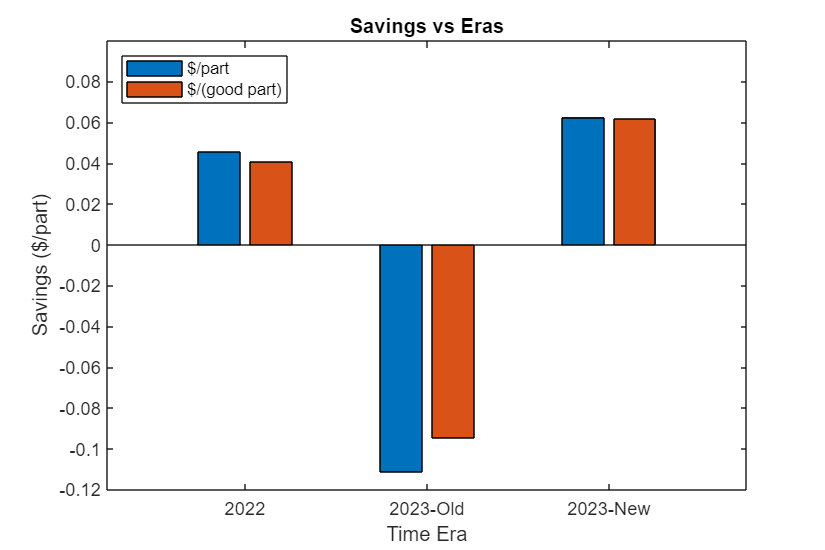

figure('Position',[0 0 600 400])
horizontal_vector = reordercats(categorical({'2022','2023-Old','2023-New'}), ...
    {'2022','2023-Old','2023-New'});
savings_vector = [good_savings_2022, savings_2022; good_savings_old_2023, savings_old_2023; 
good_savings_new_2023, savings_new_2023];

bar(horizontal_vector, savings_vector)
hold on
ylim([-.12 .1])
legend('$/part','$/(good part)',Location='northwest')
title('Savings vs Eras')
xlabel('Time Era')
ylabel('Savings ($/part)')

### Projected Savings Calculator

Enter the desired amount of parts below:

parts = 36000;

final_savings = good_savings_new_2023*parts;
lost_2023 = good_savings_old_2023*parts;
gain_2022 = good_savings_2022*parts;
fprintf('The projected savings is: $%.2f',final_savings)

The projected savings is: $2251.81

fprintf('Respectively, 2023-Old would have lost: $%.2f',abs(lost_2023))

Respectively, 2023-Old would have lost: $4008.49

fprintf('The savings difference is: $%.2f', abs(lost_2023 - final_savings))

The savings difference is: $6260.30